## Spherical Cap

The sphere of radius R cm and  density p_e g/cm^3 is submerged in seawater. The spere floats as long as its density is less than the seawater density, which is approximately p_a=1,027 gr/cm^3. 

We should find the height (h) of the portion of the float that is below the water.

According to Archimedes' Principle, the buoyancy force action on an object that is partially submerged in a fluid is equal to the weight of the fluid that is displaced by the proportion of the object that is submerged.

**Equations: **

- The spherical cap volume of heigh h is:

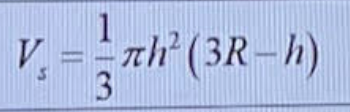 [1]

- The buoyance force is:

 [2]

- The difference betweent he buoyancy force F_g and the sphere weight F_g is:

 [3]

- The portion of the float that is submerged is obtained when the mass of the float equates the mass of the water that is displaced, this equation given by:

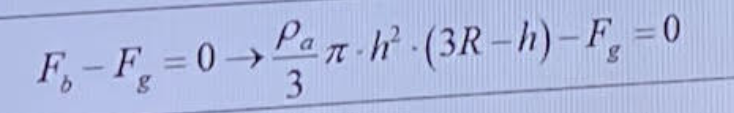 [4]

Solve for h in [4] using the following data: 

- R = 30 cm

- F_g = 4.5 N

- p_a = 1.027 g/l

- epsilon = 10^(-7)

**a. Solve the cubic equation (4) analytically. There are different approaches such as Cordano's method or Vieta substitution. **

I haven't worked with those methods previously, hence I'm providing a graphical solution with two known roots that can be used to proof-check the answer. 

p_a = 1.027

p_a = 1.0270

R = 30

R = 30

F_g = 4.5

F_g = 4.5000

sphere_cap = @(x) ((p_a / 3) * pi * x^2) * ((3 * R) - x) - F_g

sphere_cap = function_handle with value:
    @(x)((p_a/3)*pi*x^2)*((3*R)-x)-F_g


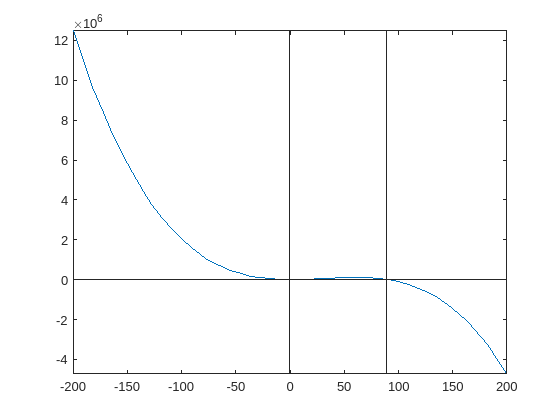

yline(0); hold on;
xline(-0.2154)
xline(89);
fplot(sphere_cap, [-200, 200]); hold off

**b.  Solve the question with the iterative algorithm shown below**

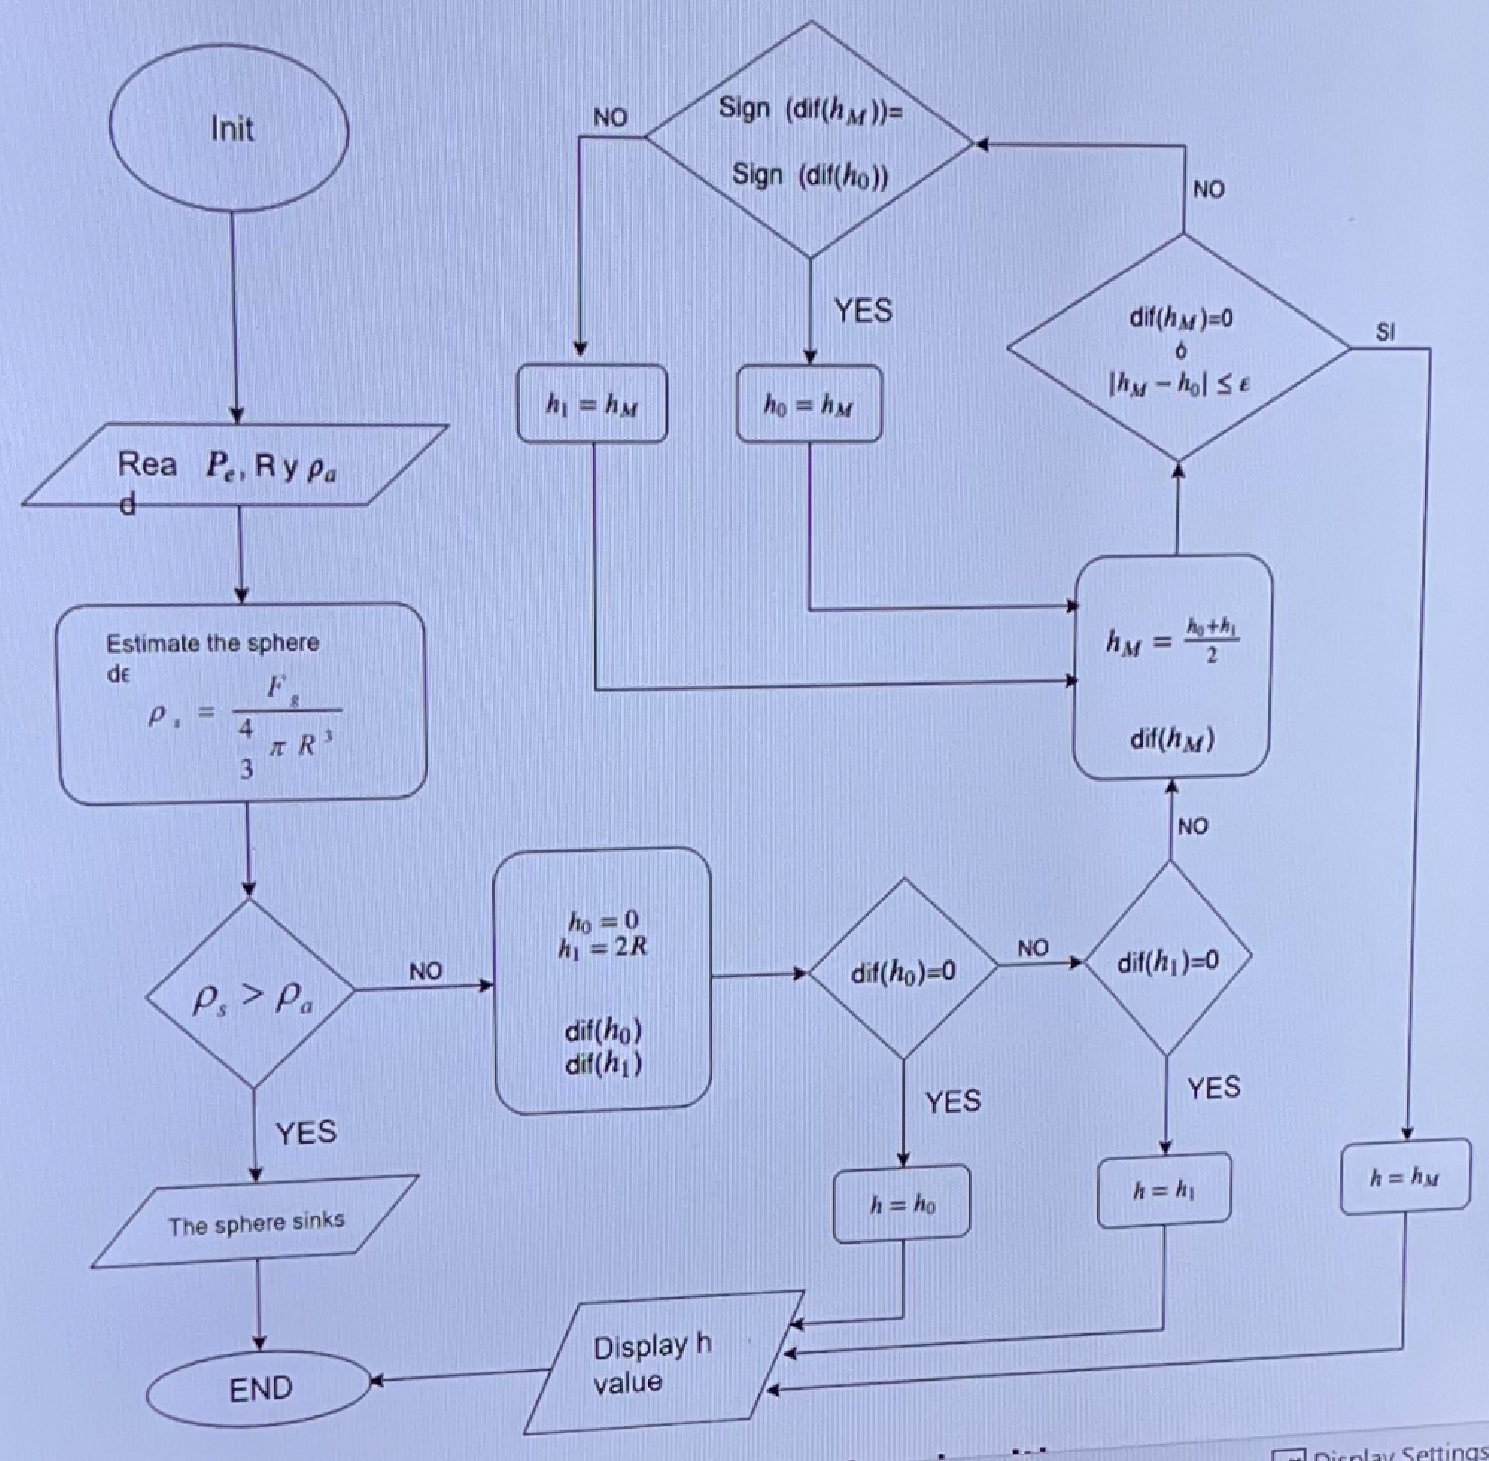

R = 30

R = 30

p_e = 1.0

p_e = 1

p_a = 1.027

p_a = 1.0270

F_g = 4.5

F_g = 4.5000

sphere_cap_pipeline(R, p_e, p_a, F_g)

p_s = 3.9789e-05

Find h


**d. Solve the equation with fzero**

fzero only returns a single root dependent on the initial value

h_init = 0

h_init = 0

h = fzero(sphere_cap, h_init)

h = -0.2154

**e. Solve the equation with the solve command availabe in the Symbolic Toolbox.**

syms x

sphere_cap_eq = ((p_a / 3) * pi * x^2) * ((3 * R) - x) - F_g == 0

$$sphere\_cap\_eq = -\frac{1027\,\pi \,x^{2}\,\left(x-90\right)}{3000}-\frac{9}{2}=0$$

h = solve(sphere_cap_eq, x, 'Real', true) 

$$h = \left(\begin{array}{c} \mathrm{root}\left(1027\,\pi \,z^{3}-92430\,\pi \,z^{2}+13500,z,1\right)\\ \mathrm{root}\left(1027\,\pi \,z^{3}-92430\,\pi \,z^{2}+13500,z,2\right)\\ \mathrm{root}\left(1027\,\pi \,z^{3}-92430\,\pi \,z^{2}+13500,z,3\right) \end{array}\right)$$

## Functions

function sphere_cap_pipeline(R, p_e, p_a, F_g)
    % Estimate the sphere d_eps
    p_s = F_g / ((4/3) * pi * R^3)
    
   
    % Decision if sphere sinks
    if p_s > p_a
        disp('The Sphere sinks')
    else
        disp('Find h')
    end
end